# Aula 13 - Exercícios de projeto em frequência

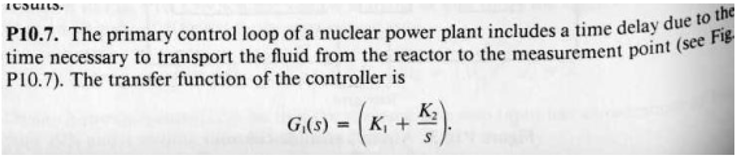

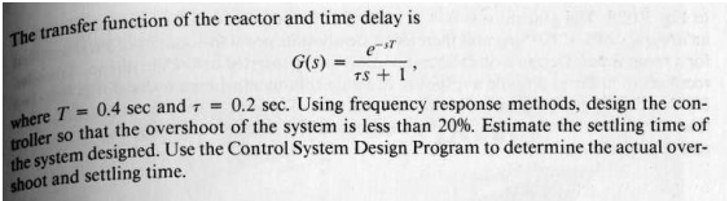

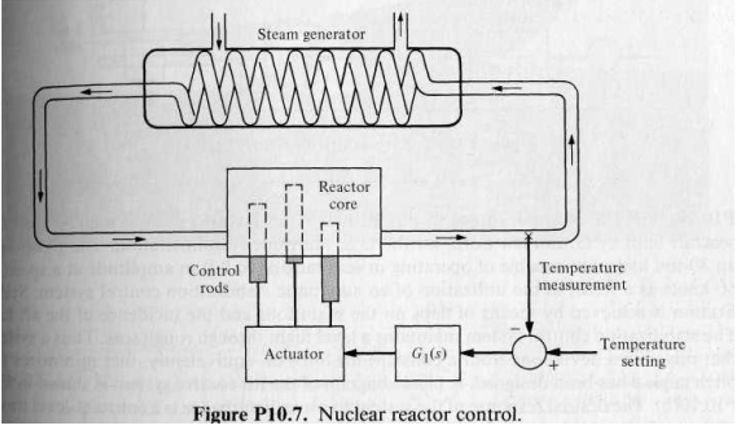

**Planta:**

$G(s)=\frac{e^{-T s}}{\tau s+1}=\frac{e^{-T s}}{\tau(s+\frac{1}{\tau})}$, onde $T=0.4$ e $\tau=0.2$ 

**Controlador PI:**

$G_1(s)=K_1+\frac{K_2}{s}=K_1\frac{s+\frac{K_2}{K_1}}{s}$, onde $K_1$ e $K_2$ devem ser determinados

**FT de malha aberta:**


$$G_{ma}(s)=G_1(s)G(s)=K_1\frac{s+\frac{K_2}{K_1}}{s}\frac{e^{-T s}}{\tau(s+\frac{1}{\tau})}$$


fazendo $\frac{K_2}{K_1}=\frac{1}{\tau}$ temos $K_2=\frac{K_1}{\tau}$ 

e


$$G_{ma}(s)=K_1\frac{e^{-T s}}{\tau s}$$


**Requisitos:**


$$M_p=20\%=0.2$$


porém, $\zeta=\frac{|ln( M_p)|}{\sqrt{\pi^2+ln^2(M_p)}}$ e $MF=100\zeta º$

logo, $MF_{desejada}=100\frac{|ln( M_p)|}{\sqrt{\pi^2+ln^2(M_p)}}º$

clear
Mp=0.2;
MF=100*abs(log(Mp))/sqrt(pi^2+(log(Mp))^2)

MF = 45.5950

Podemos encontrar o valor de $K_1$ seguindo os passos de um controlador de atraso. Como não temos um requisito de erro estacionário, vamos pular o primeiro passo.

Obter a MF para o sistema não compensado $G_c=K_c$ e a frequência de corte $\omega_c$

tau=0.2;
T=0.4;
s=tf([1 0],1);
Gma=exp(-T*s)/(tau*s);
[mag,phase,wout] = bode(Gma);
[Gm,Pm,Wcg,Wcp] = margin(Gma)

Gm = 0.7854

Pm = -24.5916

Wcg = 3.9270

Wcp = 5.0000

Vemos que, para $K_1=1$ o sistema não atende a marge margem de fase desejada.

Obter a nova frequência de corte na qual a fase $\angle{G(j\omega)}=-(180º-MF_{desejada})+\Delta$, com $\Delta=5º \tilde\ 10º$ 

delta=10;
fase=-(180-MF)+delta

fase = -124.4050

wc=interp1(phase(:),wout,fase)

wc = 1.5012

Devemos atrasar então a frequência de corte de 5rad/s para 1.5rad/s.

Obter o modulo do ganho na nova $\omega_c$. 

modulo=interp1(wout,20*log10(mag(:)),wc)

modulo = 10.4541

Um compensador de atraso deveria atenuar esse valor apenas em alta frequência, porém só temos uma parâmetro $K_1$ que nos garante um controle proporcional. Devemos então calcular o valor de $K1$ para atenuarmos esse ganho para qualquer frequência.

K1=10^(-modulo/20)

K1 = 0.3001

Com todos os parâmetros, podemos montar o controlador e simular

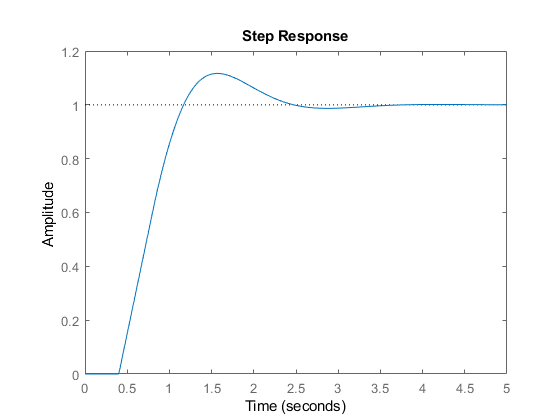

G=exp(-T*s)/(tau*s+1);
K2=K1/tau;
Gc=K1+K2/s;
sys=feedback(Gc*G,1);
step(sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.5781
    SettlingTime: 2.2746
     SettlingMin: 0.9048
     SettlingMax: 1.1167
       Overshoot: 11.6722
      Undershoot: 0
            Peak: 1.1167
        PeakTime: 1.5643
